# Wykres rozrzutu

Ten typ wykresu służy do wizualizacji zbioru punktów. Pozwala ocenić czy w danych występuje trend, skupienia, itp.

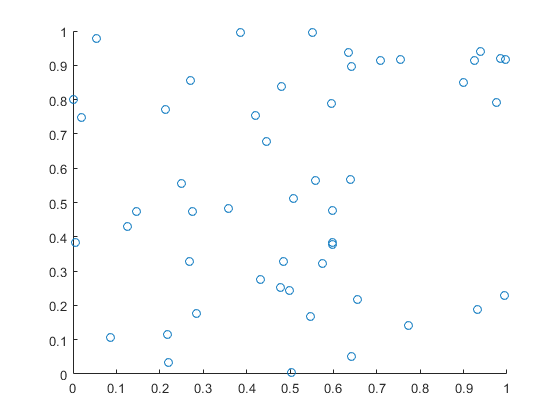

x = rand(1,50);
y = rand(1,50);
scatter(x,y)

Możliwe jest określenie koloru jak i rozmiaru punktów. Jeśli jako wartośc koloru lub rozmiaru podana zostanie pojedyncza wartość, wsyzstkie punkty będą miały taki sam rozmiar lub kolor. Jeśli podany zostanie wektor o ilości elementów odpowiadającej liczbie punktów to każdy punkt będzie miał inny kolor lub rozmiar. W poniższym przykładzi wszystkie punkty mają identyczny kolor, ale każdy z nich ma inny rozmiar.

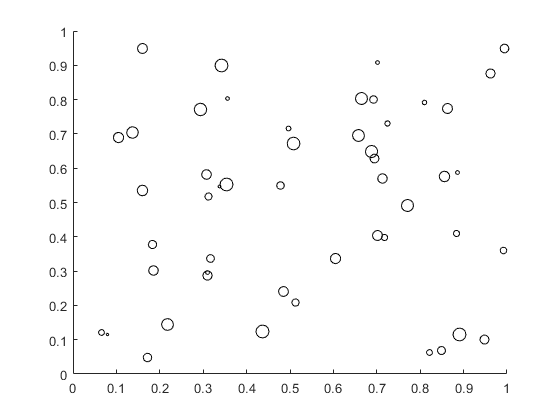

x = rand(1,50);
y = rand(1,50);
s = rand(1,50)*100;
scatter(x,y,s,"black")

W przykładzi eponiżej wszystkie punkty mają domyślny rozmiar, natomiast kolor jest zdefiniowany przez wektor c.

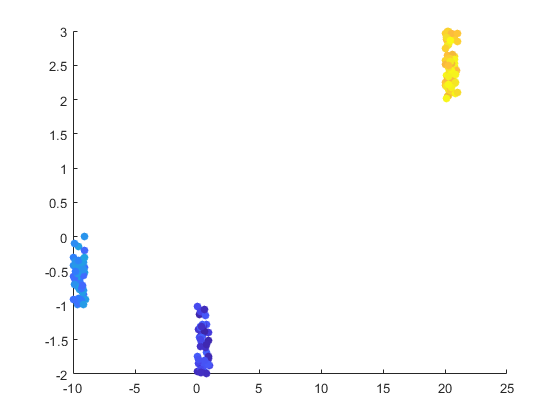

x = [rand(1,50),rand(1,70)+20,rand(1,50)-10];
y = [rand(1,50)-2,rand(1,70)+2,rand(1,50)-1];
c = [rand(1,50)-2,rand(1,70)+2,rand(1,50)-1];
scatter(x,y,[],c,"filled")

Wykresy rozrzutu są też przydatne do porównywania serii logicznie powiązanych danych. Wykres poniżej przedstawia dwie serie danych.

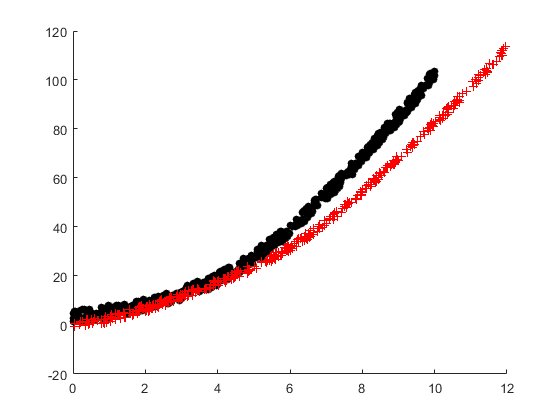

n1 = 500;
x1 = rand(1,n1)*10;
y1 = x1.^2 + sin(x1) + 1 + rand(1,n1)*5;

n2 = 432;
x2 = rand(1,n2)*12;
y2 = 0.7*x2.^2 - cos(x2) + x2 + rand(1,n2) * 3;

newplot
hold on
scatter(x1,y1,"black","filled")
scatter(x2,y2,"red","+")
hold off

Częstym przypadkiem jest umieszczanie na jednym obrazie wykresów rozrzutu i wykresu linii dopasowanej do zbioru punktów.

Wygenerowanie danych z szumem losowym (w praktyce dane te otrzymjuje się na drodze pomiarów):

n3 = 500;
x3 = rand(1,n3)*10;
y3 = 5*x3.^2 - 3*x3 + 2 + (rand(1,n3)*25-12);

Obliczenie współczynników linii regresji zgodnie ze wzorem: $\mathit{\mathbf{b}}={\left.{\left(\mathit{\mathbf{X}}\right.}^T \cdot X\right)}^{-1} \cdot {\mathit{\mathbf{X}}}^T \cdot \mathit{\mathbf{y}}$

X = [ones(n3,1) x3.' (x3.^2).'];
b = inv(X.' * X) * X.' * y3.';

Posortowanie wartości x i obliczenie wartości dopasowanej funkcji:

x3s = sort(x3);
yp = b(1) + b(2).*x3s + b(3).*x3s.^2;

Wykonanie wykresu:

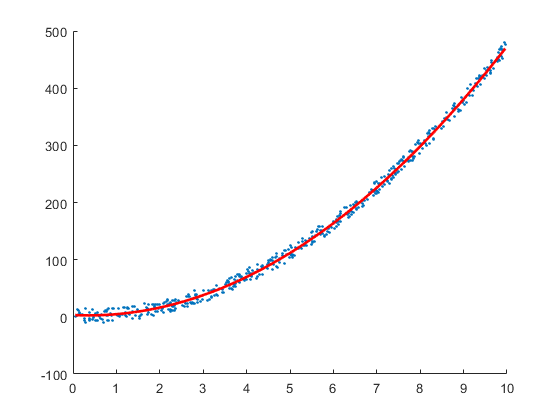

newplot()
hold on
scatter(x3,y3,5,"filled") % dane
plot(x3s,yp,"red","LineWidth",2) % dopasowana linia
hold off